inten = readmatrix("Hotwire.dat");
inten1 = transpose(inten(:,2));

n = length(inten1);
k = 160;

corrcoff1 = zeros(1,k+1);
mul = 0;
inten1flu = inten1 - mean(inten1);
rmsq1 = (rms(inten1flu))^2;

for dt = 0:k
    mul = 0;
    for t = 1:n-dt
        mul = mul + (inten1flu(1,t)*inten1flu(1,(t+dt)));
    end
    corrcoff1(dt+1) = (mul/n)/rmsq1;
end

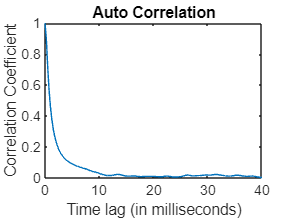

x = 0:k;
plot(x*0.25,corrcoff1)
title("Auto Correlation");
xlabel("Time lag (in milliseconds)");
ylabel("Correlation Coefficient");

y = corrcoff1;
n = 161;
h = 0.25;
sum_odd = 0;
sum_even = 0;
for i = 2:2:n-1
    sum_even = sum_even + y(i);
end

for i = 3:2:n-2
    sum_odd = sum_odd + y(i);
end
area = (h/3) * (y(1) + 4*sum_odd + 2*sum_even+y(end))

area = 2.0693